# 1.3.02 Программирование

**Практическое занятие**

Проверить, можно ли использовать `spmd` в качестве имени переменной или функции

iskeyword spmd

ans = logical
   1


## Загрузка данных

load students

## Выбрать студента (`inputdlg()`)

student = inputdlg('Введите фамилию студента:')

student = 1×1 cell array
    {'аораора'}


idx = strcmp(student,students);

## Выбрать студента (`listdlg()`)

idx = listdlg('PromptString','Выберите студента:',...
    'SelectionMode','single',...
    'ListString',students);
student = students{idx};

## Выбрать студента (`input()`)

student = input('Введите фамилию студента:','s')

student = 'хщзхщз'

idx = strcmp(student,students);

# IF-ELSE

clear
load students

Введите фамилию с буквы, чтобы увидеть, как работает Warning (предупреждение)

student = inputdlg('Введите фамилию студента:')

student = 1×1 cell array
    {'Антонов'}


student = student{1};
idx = strcmpi(student,students);

Проверяем перед вычислениями, что введенная страна найдена в переменной `country`.

if any(idx)
    studentMarks = score(idx,:)
    if ~strcmp(student,students{idx})
        warning(['Введенна фамилия ', student,'. Показаны оценки студента ',students{idx},'.'])
    end
else
    errordlg(['Студент ',student,' отсутствует в списке'])
end

studentMarks =      3     5     1     5     5     2


# SWITCH-CASE

Студет допущен к экзамену, если он сдал все работы. Если вместо оценки за работу у студента написано NaN, значит он по какой-то причине работу не сдал. 

Например, у 3 студента есть пропущенная лабораторная работа.

isnan(score(3,:))
workPassed = ~any(isnan(score(3,:)))

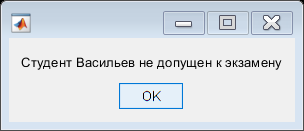

idx = listdlg('PromptString','Выберите студента:',...
    'SelectionMode','single',...
    'ListString',students);
student = students{idx};

% Выведем на экран информацию о том, допущен ли студен до экзамена.
% Т.е. нужно вывести информацию, которая может принимать конечное число
% дискретных значений: 'Допущен' и 'Не допущен'
studentMarks = score(idx,:);
workPassed = ~any(isnan(studentMarks));
switch workPassed
    case true
        msgbox(['Студент ',student,' допущен к экзамену'])
    case false
        msgbox(['Студент ',student,' не допущен к экзамену'])
end

# Циклы

## Цикл FOR

Сформируем список студентов, не допущенных к экзамену, выведем результат в виде текста.

averageScore = mean(score,2);

for n=1:length(students)
    if isnan(averageScore(n))
        str = [students{n}, ' имеет оценки: ', num2str(score(n,:))];
        disp(str)
    end
end

Васильев имеет оценки: 1  NaN    5    3    5    5
Волова имеет оценки: 5    5    4    5  NaN    5
Кузницын имеет оценки: 5    5  NaN    5    5    1
Пономарева имеет оценки: 5  NaN    5  NaN    5    5
Смирнов имеет оценки: NaN    5  NaN    5    5    5
Яковлева имеет оценки: 5  NaN    1    5    5    5


## Цикл While

Попросите пользователя ввести фамилию студента, и не закрывайте окно ввода, пока существующая фамилия не будет введена.

Инициализируем вспомогательную переменную idx как false, для того, чтобы убедиться, что цикл выполнился хотя бы один раз.

idx = false;
while ~any(idx)
    student = inputdlg('Введите фамилию студента: ');
    student = student{1};
    idx = strcmpi(student,students);
end